Now, we study delay differential equations, matlab algoritm is 

where

ddefun is delay differential equation funcion, it should be expressed like a similary for ode45 code,with the difference which now we define too the delay varibles as new states equations. We see the next example (this example is with history constant)

In ode45 we rewritte the before equation as

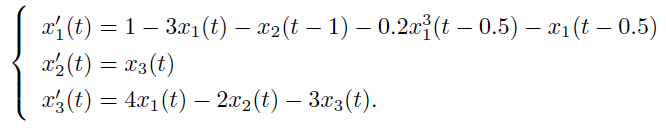

But now, the variables whit delay, we express it with z variable, as follows

f=@(t,x,Z)[1-3*x(1)-Z(2,1)-0.2*Z(1,2)^3-Z(1,2);...
           x(3);...
           4*x(1)-2*x(2)-3*x(3)]

f = function_handle with value:
    @(t,x,Z)[1-3*x(1)-Z(2,1)-0.2*Z(1,2)^3-Z(1,2);x(3);4*x(1)-2*x(2)-3*x(3)]


Note the z variable equations have two numbers, its firts number is relationed with the state equation, in other words, Z(2,1) meaning delay equation from secound state equation and the next number, one, meaning which the delay time is indicated in the firts entry of lag vector.

for solve, we now define all other parameters

lags meaning delay time for each delay equation, in this case we have two equations with delay

lags=[1 0.5]

lags =     1.0000    0.5000


history meaning the initial conditions (condiciones iniciales) for each delay fuction, this is, the behavior of each equation state before the time 0, in this example, the behavior of all state functions is constant and zero.

history=[0; 0; 0]

history =      0
     0
     0


rvt meaning time value range (rango de valores de t), in this example, we stars at time 0, ends at time 10 with 2^6 steps

rvt=linspace(0,10,2^6)

rvt =          0    0.1587    0.3175    0.4762    0.6349    0.7937    0.9524    1.1111    1.2698    1.4286    1.5873    1.7460    1.9048    2.0635    2.2222    2.3810    2.5397    2.6984    2.8571    3.0159    3.1746    3.3333    3.4921    3.6508    3.8095    3.9683    4.1270    4.2857    4.4444    4.6032    4.7619    4.9206    5.0794    5.2381    5.3968    5.5556    5.7143    5.8730    6.0317    6.1905    6.3492    6.5079    6.6667    6.8254    6.9841    7.1429    7.3016    7.4603    7.6190    7.7778


Finally, the algoritm is

tx=dde23(f,lags,history,rvt)

tx = struct with fields:
     solver: 'dde23'
    history: [3×1 double]
    discont: [0 0.5000 1 1.5000 2 2.5000 3]
          x: [1×70 double]
          y: [3×70 double]
      stats: [1×1 struct]
         yp: [3×70 double]


we plot the result 

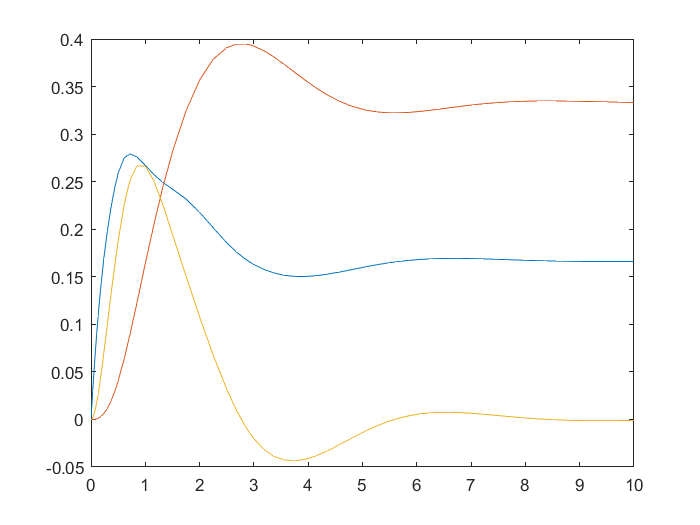

plot(tx.x,tx.y)

See the next example

f=@(t,x,Z)[1-3*x(1)-Z(2,1)-0.2*Z(1,2)^3-Z(1,2);...
           x(3);...
           4*x(1)-2*x(2)-3*x(3)]; % describe the delay ODE

In this case, behavior of each function before 0 time is different or each equation.

history=@(t)[exp(2.1*t);...
             sin(t);
             cos(t)]; % describe the history functions

All other parameters are the same

lags=[1 0.5]; 
rvt=linspace(0,10,2^12)

rvt =          0    0.0024    0.0049    0.0073    0.0098    0.0122    0.0147    0.0171    0.0195    0.0220    0.0244    0.0269    0.0293    0.0317    0.0342    0.0366    0.0391    0.0415    0.0440    0.0464    0.0488    0.0513    0.0537    0.0562    0.0586    0.0611    0.0635    0.0659    0.0684    0.0708    0.0733    0.0757    0.0781    0.0806    0.0830    0.0855    0.0879    0.0904    0.0928    0.0952    0.0977    0.1001    0.1026    0.1050    0.1074    0.1099    0.1123    0.1148    0.1172    0.1197


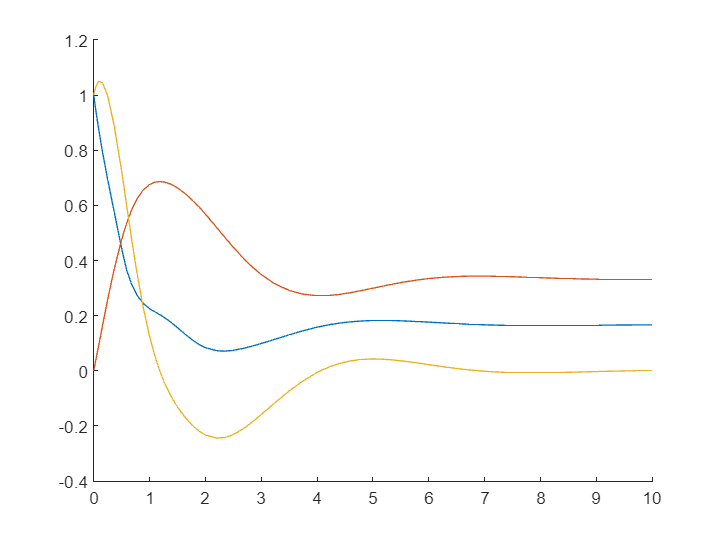

tx=dde23(f,lags,history,rvt); 
figure
hold on
plot(tx.x,tx.y)

Now, we agregate history functions to graph and plot

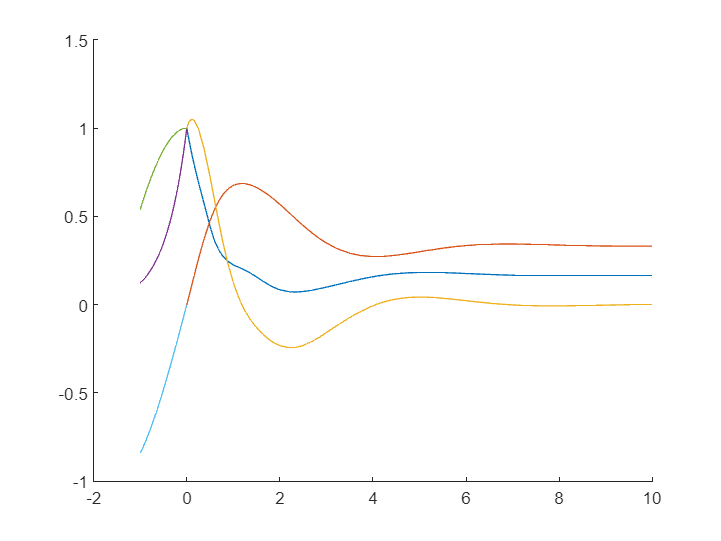

f1=@(x) exp(2.1*x);
f2=@(x) cos(x);
f3=@(x) sin(x);
figure
hold on
plot(tx.x,tx.y)
fplot(f1,[-1,0])
fplot(f2,[-1,0])
fplot(f3,[-1,0])